# Visión por Computador - Sesión 3

        Ferran Velasco Olivera

        Joaquín Gómez Sánchez

## Filtrado de ruido gausiano

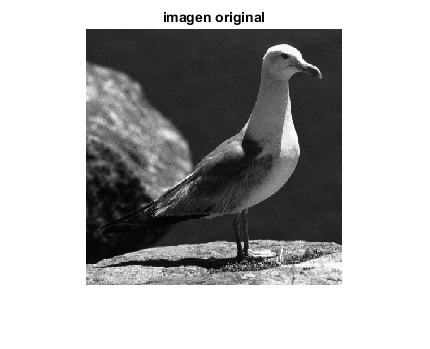

im = imread('gull.tif');
figure, imshow(im), title('imagen original')

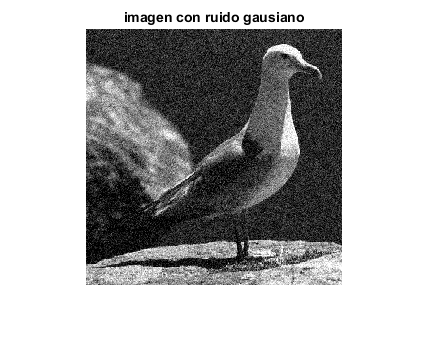


imgWNoise = imnoise(im, 'gaussian');
figure, imshow(imgWNoise), title('imagen con ruido gausiano')

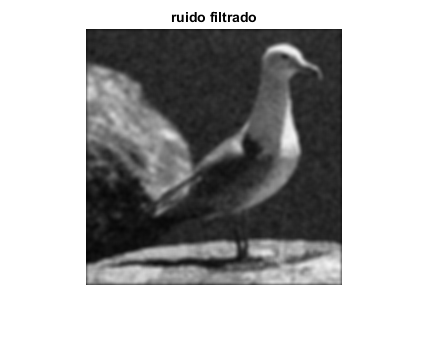


h = fspecial('gaussian', 7, 2);

imgNoiseF = imfilter(imgWNoise, h, 'conv');
figure, imshow(imgNoiseF), title('ruido filtrado')

## Filtrado con mediana de ruido salt & pepper

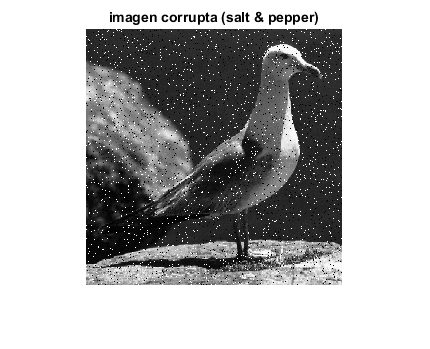

imSP = imnoise(im, 'salt & pepper');
figure, imshow(imSP), title('imagen corrupta (salt & pepper)')

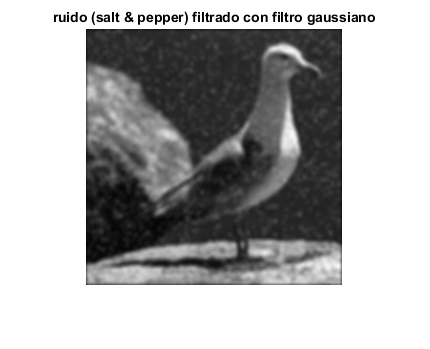


imSPFLineal = imfilter(imSP, h);
figure, imshow(imSPFLineal), title('ruido (salt & pepper) filtrado con filtro gaussiano')

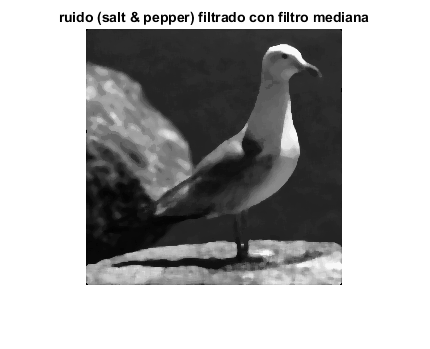


imSPFMedian = medfilt2(imSP, [5, 5]);
figure, imshow(imSPFMedian), title('ruido (salt & pepper) filtrado con filtro mediana')

## Procesado de contornos I (Filtro gaussiano)

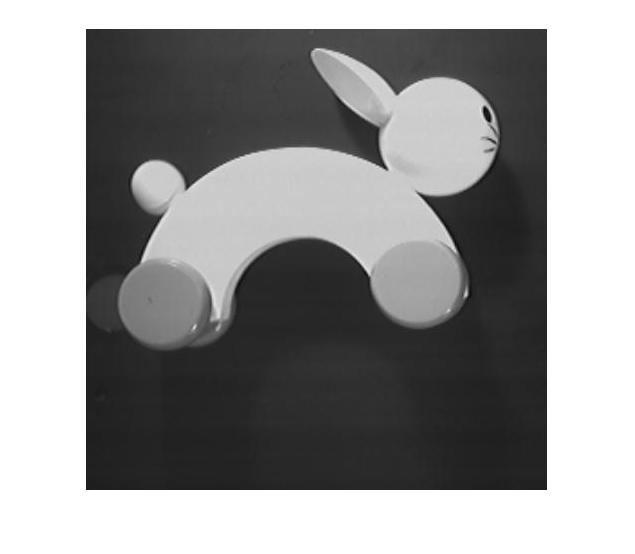

im2 = imread('rabbit.jpg');
imshow(im2)

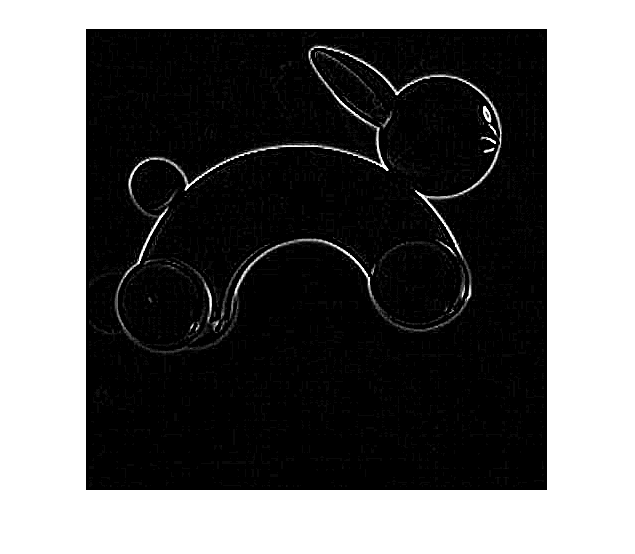


filtGauss = fspecial('gaussian', 7, 2);
im2GaussFiltered = imfilter(im2, filtGauss);

imshow((im2GaussFiltered-im2)*10)

## Procesado de contornos II (Sobel)

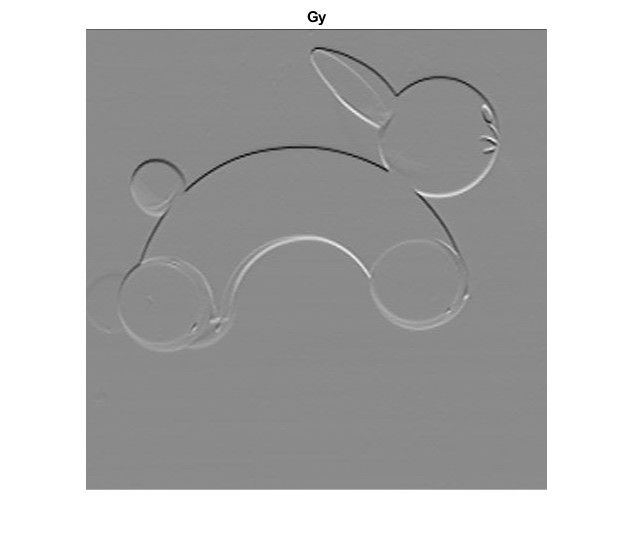

sobelFilter = fspecial('Sobel');
sobelFilter = sobelFilter/4;

gy = imfilter(double(im2), sobelFilter);
figure, imshow(gy, []), title('Gy')

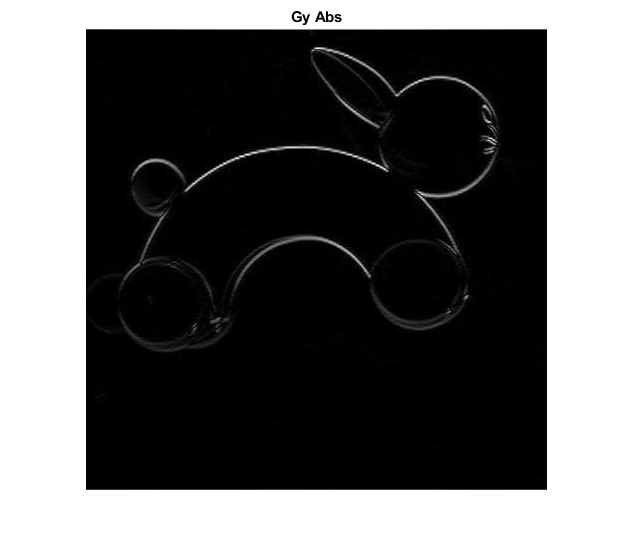

figure, imshow(abs(gy), []), title('Gy Abs')

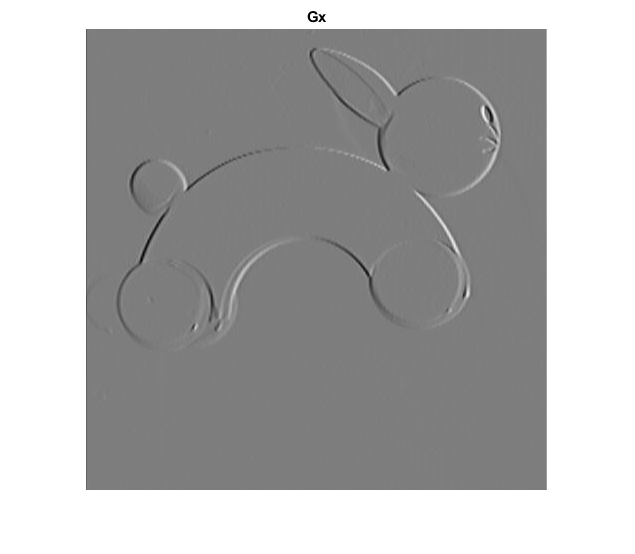


gx = imfilter(double(im2), sobelFilter');
figure, imshow(gx, []), title('Gx')

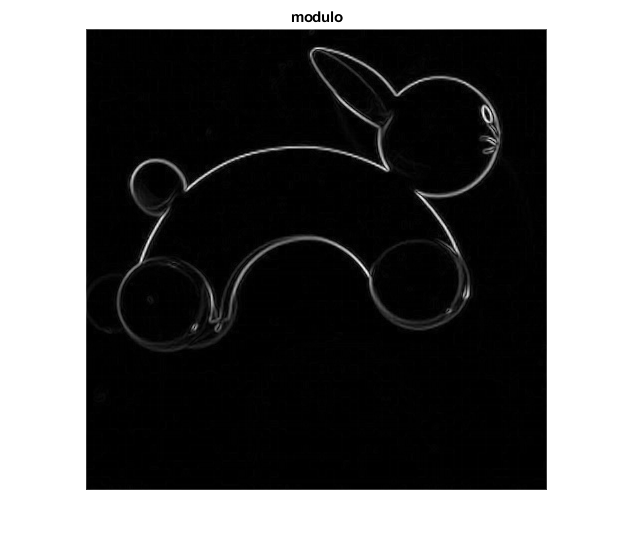


mod = sqrt(gx.^2 + gy.^2);
figure, imshow(mod, []), title('modulo')

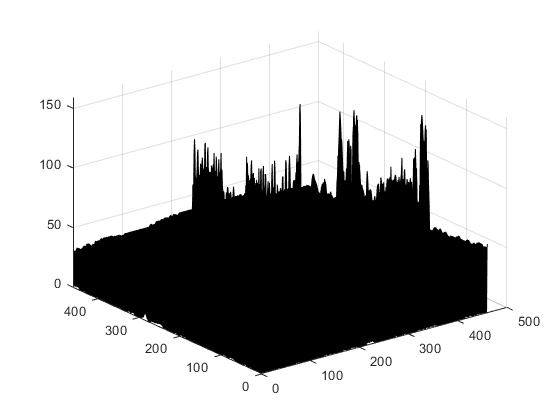


figure, surf(mod)

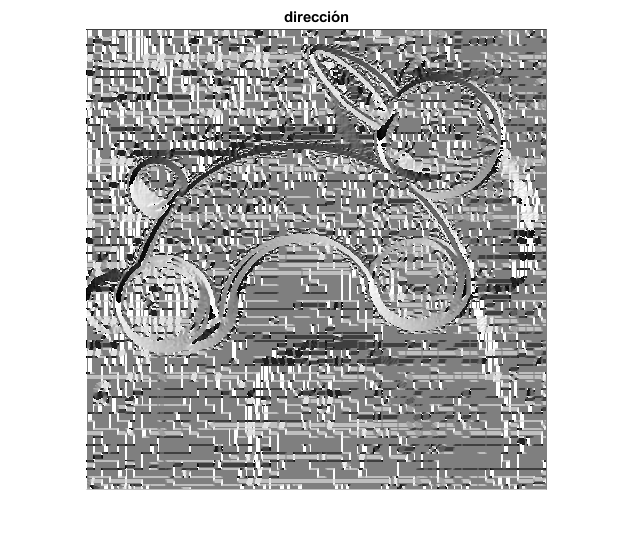


dir = atan2(gy, gx);
figure, imshow(dir, []), title('dirección')

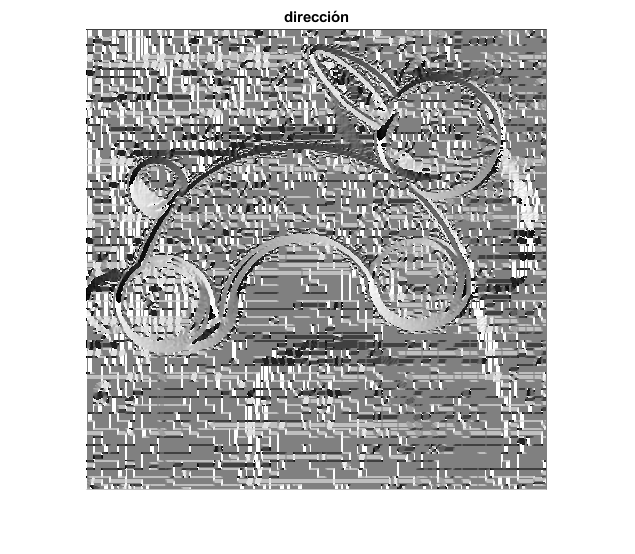


dir = dir + pi;
dir = dir/2/pi;
dir = uint8(dir*255);
figure, imshow(dir, []), title('dirección')

## Laplaciano

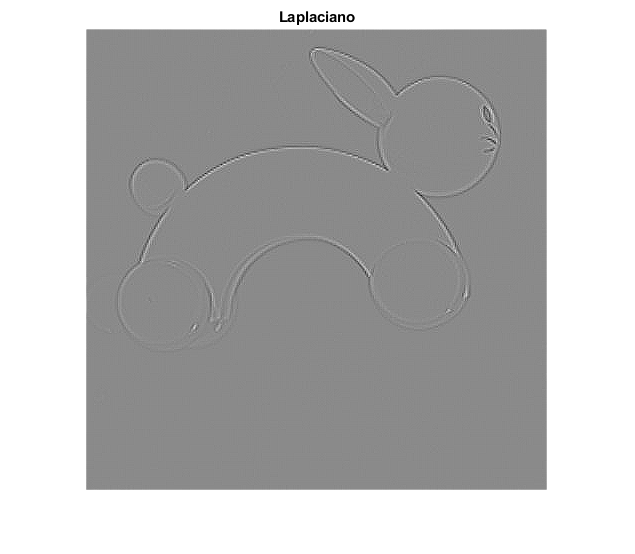

h = [0 -1 0; -1 4 -1; 0 -1 0];
lap = imfilter(double(im2), h);
figure, imshow(lap, []), title('Laplaciano')

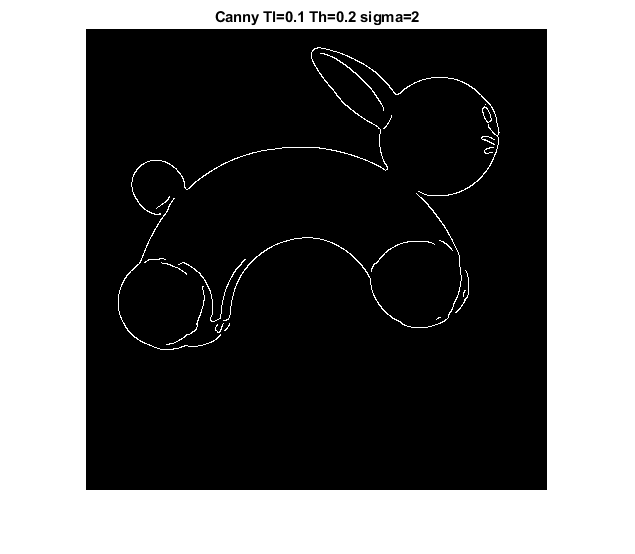


res = edge(im2, 'canny', [0.1 0.2], 2);
figure, imshow(res), title('Canny Tl=0.1 Th=0.2 sigma=2')

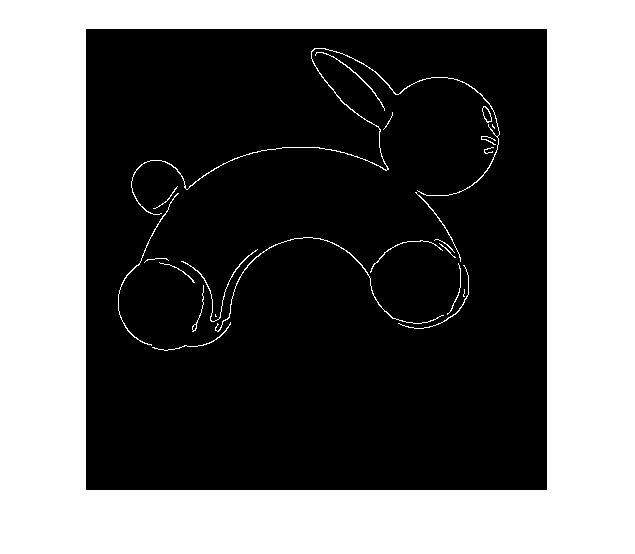


res = edge(im2, 'canny', [0.05 0.2], 1.5);
figure, imshow(res)